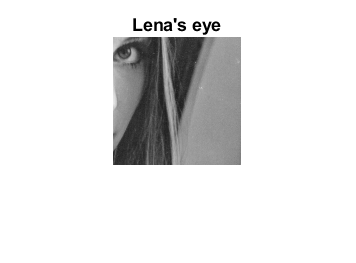

load lena512.mat
lenarec=lena512(252:379,318:445); 
figure(1);
imshow(uint8(lenarec))
title("Lena's eye");

b = de2bi(lenarec,8,'left-msb'); % Convert the samples from uint8 to binary
b = b';     
bits = b(:);

bits2send = bits';
Fs= 96000;
mp= 10;
%No_bits= 8712;
Baud_rate= Fs/mp   %Symbols per second

Baud_rate = 9600

Bit_rate=Baud_rate % bits/s

Bit_rate = 9600

Ts=1/Fs;
% The bit rate is Rb= Rs= Fs / mp, because 1 bit= 1 symbol and  every symbol has mp
% samples per bit


## half-sine and rec

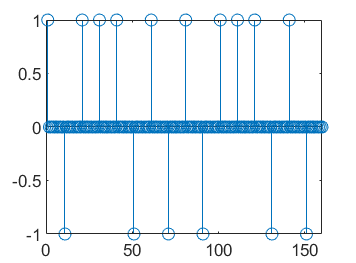


n= 0:(mp-1);
w = pi/mp;
hs = sin(w*n);

pnrz=ones(1,mp);

s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))


xPNRZ_hs=conv(hs,s); %Pulse half sine
xPNRZ=conv(pnrz,s); %Pulse rectangular


## Eye diagram pow 1


figure();
pow = sum(xPNRZ_hs.^2)/numel(xPNRZ_hs);
pow_Deseada = 1;
xPNRZ_hs = sqrt(pow_Deseada/pow)*xPNRZ_hs;
%eyediagram(xPNRZ_hs,2*mp);
figure();
%plot(xPNRZ(1:mp*16))
pow = sum(xPNRZ.^2)/numel(xPNRZ);
pow_Deseada = 1;
xPNRZ = sqrt(pow_Deseada/pow)*xPNRZ;
%eyediagram(xPNRZ,2*mp);


## filtro


orden=60;     % Orden del Filtro 
f=   [0 0.6 0.6 1];  % Vector de Frecuencias
m= [1 1 0 0]; % Vector de Magnitudes 
f1 = fir2(orden,f,m);  % Coeficientes del Filtro usando FIR2( ) 
%fvtool(f1);    
 
xPNRZ_filtrado_f1 = conv(xPNRZ_hs,f1);
eyediagram(xPNRZ_filtrado_f1,2*mp);

xPNRZ_filtrado_f2 = conv(xPNRZ,f1);
eyediagram(xPNRZ_filtrado_f2,2*mp);